# PV Orientation

clear all;
close all;

## Grundgerüst

%Umwandlung von dem Abgabedatum
%datum = datetime('2024-10-17');
%doy = day(datum, "dayofyear");
doy= 1:1:365;
% Berechne delta in Grad
delta = 23.45 * sind((360/365) * (doy + 284));
% Zeit
t_h= 1:0.5:24;
t_j = 1:1:365;
% Standortbreite in Grad für IBK
phi = 47.27;

% Berechne den Winkel alpha für verschiedene Stunden t
% Alpha = Höhenwinkel
alpha = @(t) asind((sind(phi) * sind(delta(291))) + (cosd(phi) * cosd(delta(291)) * cosd(15*(t - 12))));
alpha_values_h = alpha(t_h)

alpha_values_h =   -51.2896  -48.7884  -45.5373  -41.7016  -37.4266  -32.8316  -28.0118  -23.0435  -17.9894  -12.9030   -7.8321   -2.8224    2.0804    6.8281   11.3682   15.6423   19.5850   23.1233   26.1783   28.6685   30.5159   31.6542   32.0390   31.6542   30.5159   28.6685   26.1783   23.1233   19.5850   15.6423   11.3682    6.8281    2.0804   -2.8224   -7.8321  -12.9030  -17.9894  -23.0435  -28.0118  -32.8316  -37.4266  -41.7016  -45.5373  -48.7884  -51.2896  -52.8761  -53.4210


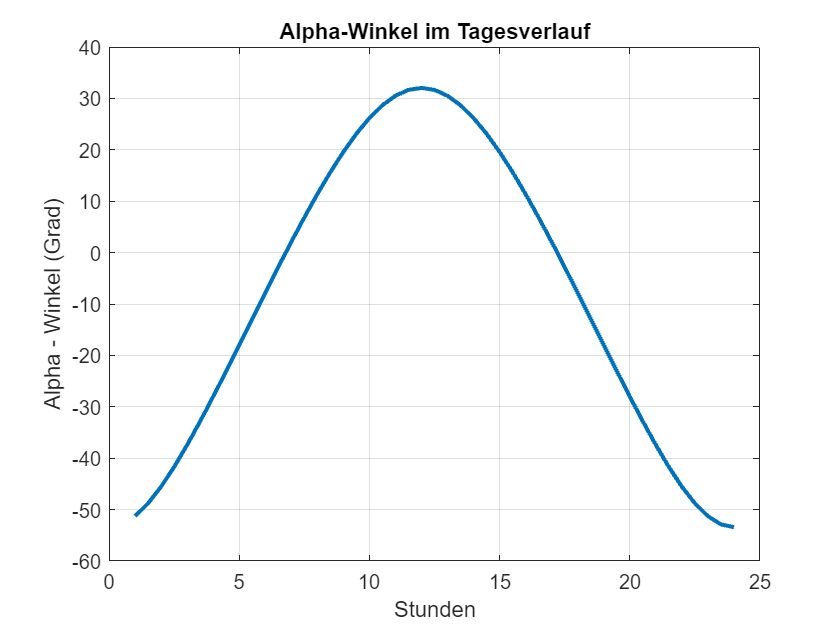

figure;
plot(t_h, alpha_values_h, 'LineWidth', 2);
xlabel('Stunden');
ylabel('Alpha - Winkel (Grad)');
title('Alpha-Winkel im Tagesverlauf');
grid on;

% %Methode2
% for t = 1:24
%      alpha(t) = asind((sind(phi) * sind(delta)) + (cosd(phi) * cosd(delta) * cosd(15*(t - 12))));
% end


%Sonnenaufgang
time_up = -(acosd(-tand(phi)*tand(delta)) / 15) + 12

time_up =     7.8248    7.8171    7.8087    7.7996    7.7900    7.7797    7.7689    7.7574    7.7454    7.7328    7.7197    7.7059    7.6917    7.6769    7.6616    7.6457    7.6294    7.6126    7.5953    7.5775    7.5593    7.5406    7.5215    7.5020    7.4820    7.4617    7.4410    7.4199    7.3984    7.3766    7.3544    7.3319    7.3091    7.2860    7.2625    7.2388    7.2148    7.1905    7.1660    7.1412    7.1161    7.0909    7.0654    7.0397    7.0137    6.9876    6.9613    6.9348    6.9082    6.8813



time_up_dateformat= datestr( time_up/24, "HH:MM:SS");

%Sonnenuntergang
time_down = (acosd(-tand(phi)*tand(delta)) / 15) + 12

time_down =    16.1752   16.1829   16.1913   16.2004   16.2100   16.2203   16.2311   16.2426   16.2546   16.2672   16.2803   16.2941   16.3083   16.3231   16.3384   16.3543   16.3706   16.3874   16.4047   16.4225   16.4407   16.4594   16.4785   16.4980   16.5180   16.5383   16.5590   16.5801   16.6016   16.6234   16.6456   16.6681   16.6909   16.7140   16.7375   16.7612   16.7852   16.8095   16.8340   16.8588   16.8839   16.9091   16.9346   16.9603   16.9863   17.0124   17.0387   17.0652   17.0918   17.1187


time_down_dateformat= datestr( time_down/24, "HH:MM:SS");

%Uptime Sonne
% Umwandlung in duration-Objekte
decimalHours = time_down-time_up;

% Umwandlung in ein duration-Objekt
timeDuration = hours(decimalHours);

% Festlegen des Formats auf "hh:mm:ss"
timeDuration.Format = 'hh:mm:ss';

% Ausgabe
[maxDuration, pos_max]= max(timeDuration(:))

maxDuration = duration
   15:44:03


pos_max = 172

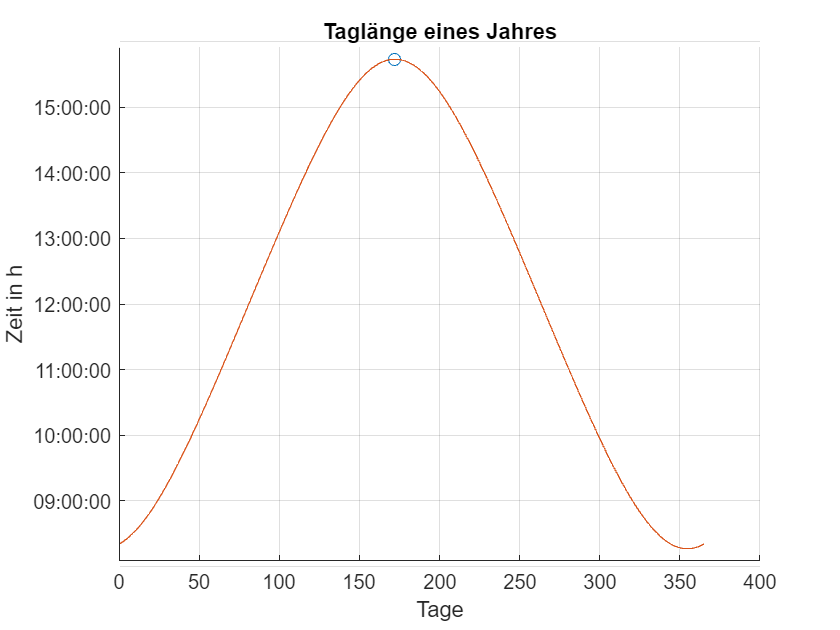


figure;
hold on
plot(pos_max,maxDuration,'o');
plot(t_j,timeDuration);
xlabel("Tage");
ylabel("Zeit in h")
title("Taglänge eines Jahres")
grid on;
hold off

%Azimut
azimut_winkel = @(t,alpha)  real(acosd((sind(delta)-sind(alpha(t)).*sind(phi)) ./ (cosd(alpha(t)).*cosd(phi))));
azimut_wikel_value_h = azimut_winkel(t_h,alpha)

Arrays have incompatible sizes for this operation.

Error in Main>@(t,alpha)real(acosd((sind(delta)-sind(alpha(t)).*sind(phi))./(cosd(alpha(t)).*cosd(phi)))) (line 59)
azimut_winkel = @(t,alpha)  real(acosd((sind(delta)-sind(alpha(t)).*sind(phi)) ./ (cosd(alpha(t)).*cosd(phi))));

Related documentation

figure;
plot(t_h, azimut_wikel_value_h, 'LineWidth', 2);
xlabel('Stunden');
ylabel('Azimut-Winkel (Grad)');
title('Azimut-Winkel im Tagesverlauf');
grid on;
%Vektor zur Sonne

